%this is for jet
wp=40

wp = 40

we_w0=0.4

we_w0 = 0.4000


Range=1000*1000     %in metres

Range = 1000000

sfc_cruise_jet=0.9/(2.2*3600*9.81) %(0.9)*2.8394e-05*9.8 %0.00016667    %0.3/(3600*1000)    %(0.9)*2.8394e-05*9.8

sfc_cruise_jet = 1.1584e-05

sfc_loiter_jet=(0.8)/(2.2*3600*9.8) %(0.8)*2.8394e-05*9.8 0.00014

sfc_loiter_jet = 1.0307e-05

velocity_cruise=500*5/18

velocity_cruise = 138.8889

velocity_loiter=200*5/18

velocity_loiter = 55.5556

Endurance=20*60 %in seconds

Endurance = 1200

L_D=6:14

L_D =      6     7     8     9    10    11    12    13    14


w3_w2=zeros(length(L_D),1);
w5_w4=zeros(length(L_D),1);
w1_w0=0.98

w1_w0 = 0.9800

w2_w1=0.97

w2_w1 = 0.9700

for i=1:length(L_D)
    w3_w2(i)=exp(-(Range*sfc_cruise_jet/(velocity_cruise*L_D(i))));
end
w3_w2

w3_w2 =     0.9862
    0.9882
    0.9896
    0.9908
    0.9917
    0.9924
    0.9931
    0.9936
    0.9941


w4_w3=0.99

w4_w3 = 0.9900

for i=1:length(L_D)
    w5_w4(i)=exp(-(Endurance*sfc_loiter_jet/L_D(i)));
end
w5_w4

w5_w4 =     0.9979
    0.9982
    0.9985
    0.9986
    0.9988
    0.9989
    0.9990
    0.9990
    0.9991


w6_w5=0.997

w6_w5 = 0.9970

w6_w0=w1_w0*w2_w1*w4_w3*w6_w5*(w3_w2.*w5_w4)

w6_w0 =     0.9234
    0.9255
    0.9271
    0.9283
    0.9293
    0.9301
    0.9308
    0.9314
    0.9319


wf_w0=(1-w6_w0)

wf_w0 =     0.0766
    0.0745
    0.0729
    0.0717
    0.0707
    0.0699
    0.0692
    0.0686
    0.0681


w0=zeros(length(L_D),1);
r=(1-wf_w0-we_w0);
for i=1:length(L_D)
    w0(i)=wp/r(i);
end
w0

w0 =    76.4215
   76.1149
   75.8862
   75.7089
   75.5676
   75.4522
   75.3562
   75.2752
   75.2058


wf=wf_w0.*w0

wf =     5.8529
    5.6690
    5.5317
    5.4254
    5.3405
    5.2713
    5.2137
    5.1651
    5.1235


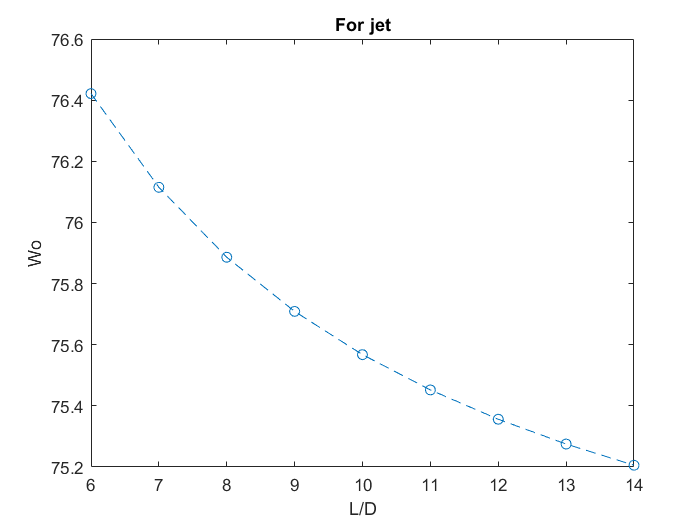

plot(L_D,w0,"LineStyle","--","Marker","o")
title("For jet")
xlabel("L/D")
ylabel("Wo")

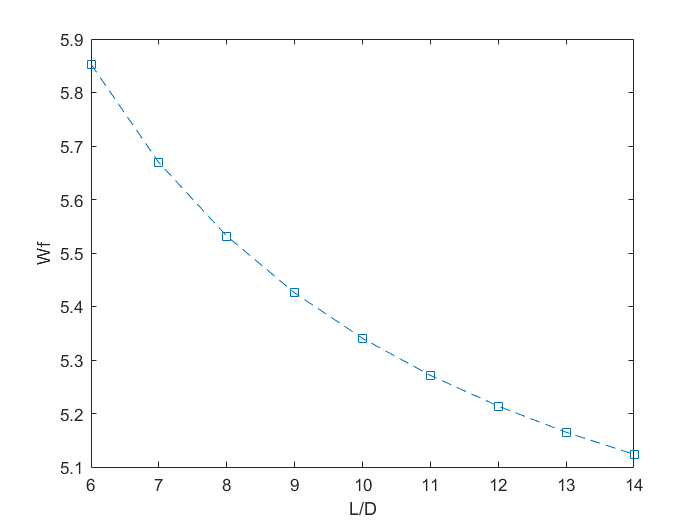

plot(L_D,wf,"LineStyle","--","Marker","square")
xlabel("L/D")
ylabel("Wf")